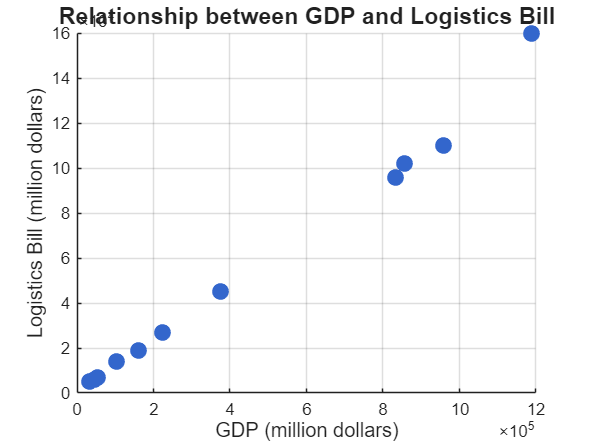

% data input
Country = {'Belgium'; 'Denmark'; 'France'; 'Germany'; 'Greece'; 'Ireland'; 
           'Italy'; 'Netherlands'; 'Portugal'; 'Spain'; 'U.K.'};

GDP = [161800; 104100; 956900; 1189100; 53400; 33900; 
       856800; 223600; 45300; 375700; 832600]; % million dollars

Logistics_Bill = [19000; 14000; 110000; 160000; 7000; 5000; 
                  102000; 27000; 6000; 45000; 96000]; % million dollars

% boxplot
figure('Position', [100 100 800 600]);
scatter(GDP, Logistics_Bill, 100, 'filled', 'MarkerFaceColor', [0.2 0.4 0.8]);
xlabel('GDP (million dollars)', 'FontSize', 12);
ylabel('Logistics Bill (million dollars)', 'FontSize', 12);
title('Relationship between GDP and Logistics Bill', 'FontSize', 14);
grid on;




%% (b) regression analysis and 95% CI
% linear regression model
X = log(GDP);
Y = log(Logistics_Bill);

% Fit linear model using fitlm
mdl = fitlm(X, Y);

% display the result
disp('========== result of the regression analysis ==========');

========== result of the regression analysis ==========


disp(mdl);


Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    -1.5792      0.19272    -8.1944    1.8263e-05
    x1             0.95996     0.015531     61.811    3.8291e-13


Number of observations: 11, Error degrees of freedom: 9
Root Mean Squared Error: 0.0651
R-squared: 0.998,  Adjusted R-Squared: 0.997
F-statistic vs. constant model: 3.82e+03, p-value = 3.83e-13


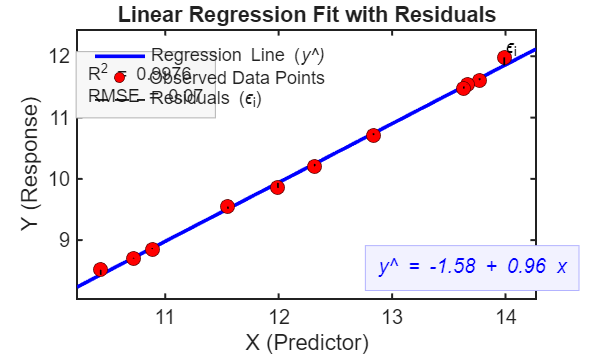


% Extract stats
a = mdl.Coefficients.Estimate(1); % intercept
b = mdl.Coefficients.Estimate(2); % slope
Y_pred = predict(mdl, X);
R2 = mdl.Rsquared.Ordinary;
RMSE = mdl.RMSE;

% --- Residuals ---
residuals_tbl = table(mdl.Fitted, mdl.Residuals.Raw, zscore(mdl.Residuals.Raw), mdl.Residuals.Standardized, ...
                      'VariableNames', {'Fitted Vals', 'Residuals', 'zscore residuals', 'Standardised'});











%Extracting values from the model (mdl)
raw_resid          = mdl.Residuals.Raw;          % observed - fitted
standardised_res   = zscore(mdl.Residuals.Raw);  % zscore standardised residuals
fitted_vals        = mdl.Fitted;                 % same as Y_pred
obs_index          = (1:numel(X))';              % "Order" (observation number)

% --- Generate smooth line for plotting the regression line ---
X_line = linspace(min(X)*0.98, max(X)*1.02, 200)';    
Y_line = predict(mdl, X_line);

%% --- Plot ---
figure('Color','w','Position',[200 200 900 540]);
hold on;

% 1. Regression line (ŷ)
plot(X_line, Y_line, 'b-', 'LineWidth', 2.2);

% 2. Observed data points
scatter(X, Y, 70, 'r', 'filled', 'MarkerEdgeColor', [0.4 0 0]);

% 3. Residual "sticks" for each point
for i = 1:length(X)
    plot([X(i) X(i)], [Y_pred(i) Y(i)], 'k--', 'LineWidth', 1);
end

% 4. Label one of the residuals εᵢ for teaching
[~, worstIdx] = max(abs(mdl.Residuals.Raw));
text(X(worstIdx), (Y(worstIdx)+Y_pred(worstIdx))/2, '\epsilon_i', ...
     'FontSize',11,'Color','k','HorizontalAlignment','left','VerticalAlignment','bottom');

% --- Compute coordinate bounds for flexible annotation placement ---
x_min = min(X_line);
x_max = max(X_line);
y_min = min([Y; Y_line]);
y_max = max([Y; Y_line]);

% 5. Annotate regression line
eqnStr = sprintf('\\ity\\^ = %.2f + %.2f x', a, b);
text(x_max - 0.35*(x_max - x_min), ...
     y_min + 0.08*(y_max - y_min), ...
     eqnStr, ...
     'Color','b','FontSize',12,'FontAngle','italic', ...
     'BackgroundColor',[0.95 0.95 1], 'EdgeColor',[0.7 0.7 1], ...
     'Margin',6,'Clipping','on');

% 6. Stats box (R² and RMSE) in top-left corner
statsStr = sprintf('R^2 = %.4f\nRMSE = %.2f', R2, RMSE);
text(x_min + 0.02*(x_max - x_min), ...
     y_max - 0.15*(y_max - y_min), ...
     statsStr, ...
     'Color',[0.1 0.1 0.1],'FontSize',11, ...
     'BackgroundColor',[0.97 0.97 0.97], 'EdgeColor',[0.7 0.7 0.7], ...
     'Margin',6,'Clipping','on');

% Axes labels & appearance
xlabel('X (Predictor)','FontSize',12);
ylabel('Y (Response)','FontSize',12);
set(gca,'LineWidth',1.2,'FontSize',12,'Box','on');

xlim([x_min x_max]);
ylim([y_min - 0.05*(y_max - y_min), y_max + 0.08*(y_max - y_min)]);

% Legend
legend({'Regression Line (\ity\^)', 'Observed Data Points', 'Residuals (\epsilon_i)'}, ...
       'Location','northwest','Box','off','Interpreter','tex');

title('Linear Regression Fit with Residuals','FontSize',13);
hold off;

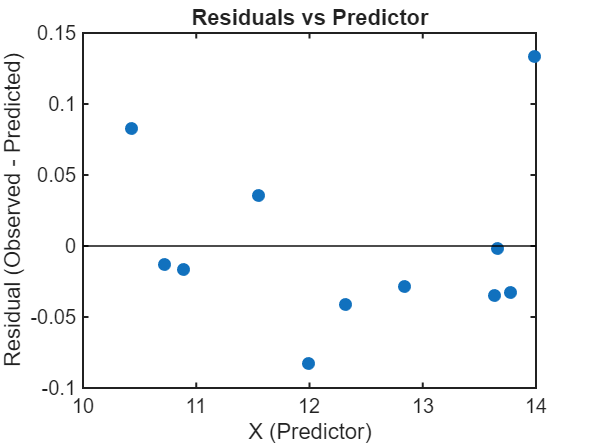


%% --- 1. Residual diagnostics plot ---
figure('Color','w','Position',[250 250 560 420]);
scatter(X, raw_resid, 60, 'filled');
yline(0,'k-','LineWidth',1.2);
xlabel('X (Predictor)','FontSize',12);
ylabel('Residual (Observed - Predicted)','FontSize',12);
title('Residuals vs Predictor','FontSize',13);
set(gca,'LineWidth',1.2,'FontSize',12,'Box','on');

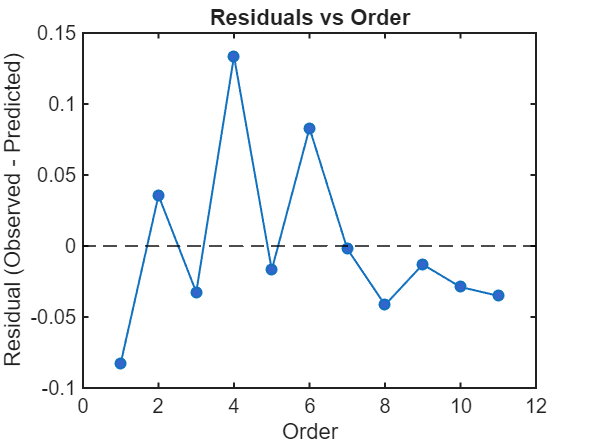


%% --- 2. Residuals vs Order (Independence check)
figure('Color','w','Position',[260 260 560 420]);
plot(obs_index, raw_resid, '-o', 'LineWidth',1.2, 'MarkerFaceColor',[0.2 0.4 0.8]);
yline(0,'k--','LineWidth',1.2);
xlabel('Order','FontSize',12);
ylabel('Residual (Observed - Predicted)','FontSize',12);
title('Residuals vs Order','FontSize',13);
set(gca,'LineWidth',1.2,'FontSize',12,'Box','on');

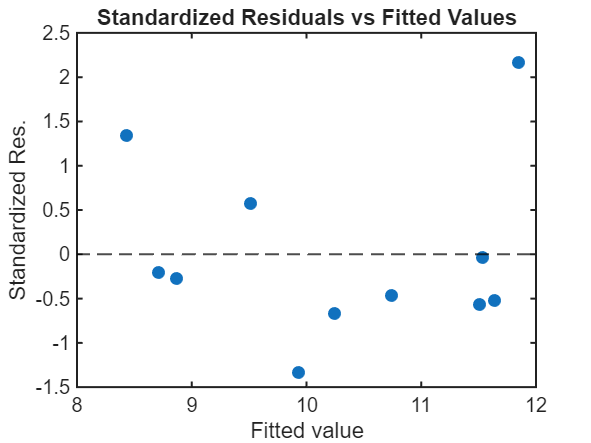


% Interpretation:
% - We want randomness around 0, not clear upward/downward trends or cycles.
% - Obvious structure would suggest non-independence / time effects / drift.

%% --- 3. Standardised Residuals vs Fitted Values
figure('Color','w','Position',[280 280 560 420]);
scatter(fitted_vals, standardised_res, 60, 'filled');
yline(0,'k--','LineWidth',1.2);
xlabel('Fitted value','FontSize',12);
ylabel('Standardized Res.','FontSize',12);
title('Standardized Residuals vs Fitted Values','FontSize',13);
set(gca,'LineWidth',1.2,'FontSize',12,'Box','on');

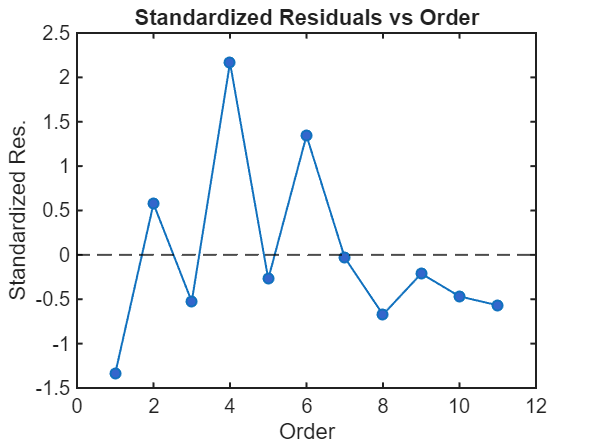


%% --- 4. Standardised Residuals vs Order
figure('Color','w','Position',[270 270 560 420]);
plot(obs_index, standardised_res, '-o', 'LineWidth',1.2, 'MarkerFaceColor',[0.2 0.4 0.8]);
yline(0,'k--','LineWidth',1.2);
xlabel('Order','FontSize',12);
ylabel('Standardized Res.','FontSize',12);
title('Standardized Residuals vs Order','FontSize',13);
set(gca,'LineWidth',1.2,'FontSize',12,'Box','on');



% Interpretation:
% • We want no "funnel" shape: if spread increases with fitted value,
%   that suggests heteroscedasticity (non-constant variance).
% • We want symmetry around 0 and roughly constant vertical spread.
% • Clear patterns/trends would indicate model misspecification
%   (e.g. missing nonlinearity).




% Descriptive statistics on residuals
residualStats = descriptiveStats(standardised_res);
% Display all descriptive stats in a table
disp(residualStats);

      Count: 11
       Mean: 2.0186e-17
        Std: 1.0000
     VarVal: 1.0000
    KurtVal: 0.1857
    SkewVal: 1.0090
        Min: -1.3351
         Q1: -0.5580
         Q2: -0.2717
         Q3: 0.4243
        Max: 2.1649




n         = residualStats.Count;      % Total number of samples
MeanVal   = residualStats.Mean;       % Sample mean
StdVal    = residualStats.Std;        % Sample std (n-1 denominator)
MinVal    = residualStats.Min;  
MaxVal    = residualStats.Max;
RangeVal  = range(standardised_res); % Max - Min

IQR = residualStats.Q3 - residualStats.Q1;   % Interquartile range

lower_bound = residualStats.Q1 - 1.5 * IQR;
upper_bound = residualStats.Q3 + 1.5 * IQR;

disp(IQR);

    0.9823



disp(lower_bound);

   -2.0315



disp(upper_bound);

    1.8978



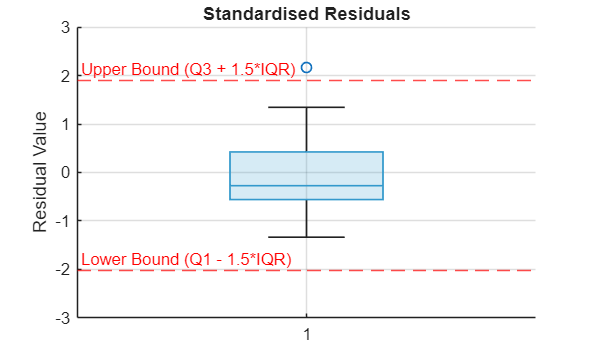


% --- Create the boxplot ---
figure;
boxchart(standardised_res, 'BoxFaceColor', [0.2 0.6 0.8]); % use boxplot(residuals) if preferred
hold on;

% --- Highlight IQR bounds on the plot ---
yline(lower_bound, '--r', 'Lower Bound (Q1 - 1.5*IQR)', 'LabelHorizontalAlignment','left');
yline(upper_bound, '--r', 'Upper Bound (Q3 + 1.5*IQR)', 'LabelHorizontalAlignment','left');

%
%  --- Enhance visual appearance ---
title('Standardised Residuals');
ylabel('Residual Value');
grid on;
hold off;





% ---  Sturges' formula and frequency table with histogram ---

% --- Calculate Sturges' number of bins ---
j = 1 + 3.322 * log10(n);
k = round(1 + 3.322 * log10(n));
classRange = (MaxVal - MinVal) / k; %could also be: classRange = range(standardised_res) / k;

fprintf('\nChi-Square Test Setup:\n');


Chi-Square Test Setup:


fprintf('\nNumber of classes = %.2f, \nRounded number of classes = %d, Class range = %.2f\n', j, k, classRange);


Number of classes = 4.46, 
Rounded number of classes = 4, Class range = 0.87


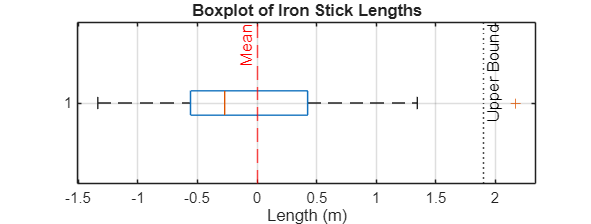


% Observed histogram and obtain their edges
% histcounts() counts how many data points fall into each bin
[histCounts, binEdges] = histcounts(standardised_res, k);

% --- Compute bin midpoints 
binCenters = binEdges(1:end-1) + classRange/2;  % Bin midpoints


%Visualisations
figure('Color','w','Position',[100 100 950 360]);
% --- Boxplot (detect outliers, spread, symmetry)
boxplot(standardised_res, 'orientation', 'horizontal');
hold on;
xline(MeanVal,'r--','Mean','LabelHorizontalAlignment','left');
xline(lower_bound,'k:','Lower Bound');
xline(upper_bound,'k:','Upper Bound');
title('Boxplot of Iron Stick Lengths');
xlabel('Length (m)');
grid on; hold off;

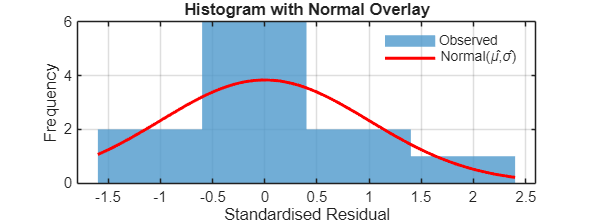


% --- Histogram with Normal PDF overlay
hObs = histogram(standardised_res, 'BinEdges', binEdges, ...
    'FaceColor', [0.3 0.6 0.8], 'FaceAlpha', 0.8, 'EdgeColor', 'none');
hold on;

% Normal PDF overlay (scaled to frequency scale: n * bin width)
x = linspace(binEdges(1), binEdges(end), 400);
y = normpdf(x, MeanVal, StdVal) * n * classRange;
hPdf = plot(x, y, 'r-', 'LineWidth', 1.8);

title('Histogram with Normal Overlay');
xlabel('Standardised Residual'); ylabel('Frequency');

% Legend at top-right
legend([hObs, hPdf], {'Observed', 'Normal(\mû,\sigmâ)'}, ...
       'Location', 'northeast', 'Box', 'off');
grid on; hold off;






% 
% --- Compute observed and expected frequencies (Chi-square components) ---
% normcdf() gives cumulative probability of the Normal distribution
cdf_edges = normcdf(binEdges, MeanVal, StdVal);

% diff() computes differences between consecutive CDF values
bin_prob = diff(cdf_edges);

% Expected count = n × Pᵢ
expected = n * bin_prob;

% Tables for inspection
LengthBins = binCenters(:);
Observed   = histCounts(:); %Frequency
Expected   = expected(:);

% --- Table for inspection ---
Classes_number = (1:k)';  % 0-based class numbering
Table_Observed = table(Classes_number, LengthBins, Observed, Expected, ...
    'VariableNames', {'Class', 'Standard_Residuals','Observed','Expected'});
disp(Table_Observed);

    Class    Standard_Residuals    Observed    Expected
    _____    __________________    ________    ________

      1           -1.1625             2          2.414 
      2           -0.1625             6         4.1929 
      3            0.8375             2          2.902 
      4            1.8375             1        0.79815 




% Quick sanity check
fprintf('Sum Observed = %.0f, Sum Expected = %.0f (should both be ~ n=%d)\n', ...
        sum(histCounts), sum(expected), n);

Sum Observed = 11, Sum Expected = 10 (should both be ~ n=11)


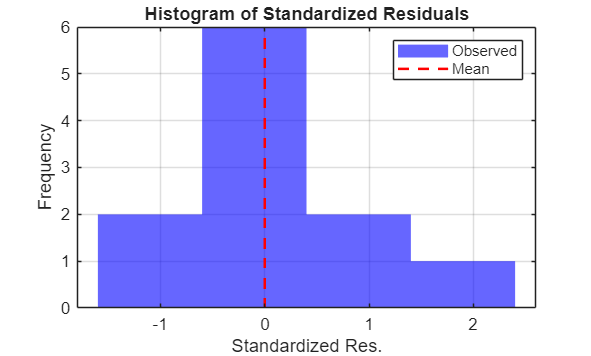


% --- Plot histogram of observed frequencies ---
figure;
histogram(standardised_res, k, 'FaceColor', [0 0 1], 'EdgeColor', 'none');
hold on;

% --- Add vertical line for mean ---
yl = ylim;
plot([MeanVal MeanVal], yl, 'r--', 'LineWidth', 1.5);

% --- Enhance the appearance ---
title('Histogram of Standardized Residuals');
xlabel('Standardized Res.');
ylabel('Frequency');
legend({'Observed','Mean'}, 'Location', 'northeast');
grid on;
hold off;

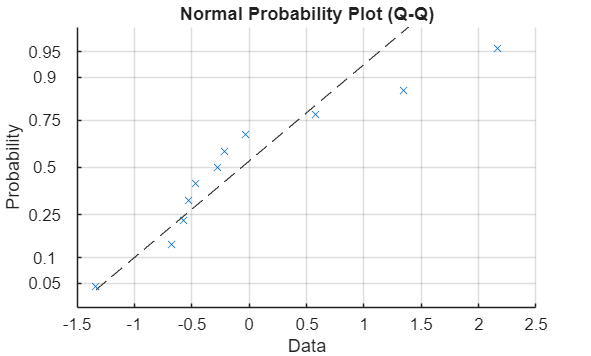


% Normal Probability Plot (Q-Q plot)
figure('Color','w');
probplot('normal', standardised_res);
title('Normal Probability Plot (Q-Q)');
grid on;


% Theory:
% If residuals are normal → Q-Q points lie near diagonal line.




%% --- Chi-square style residual analysis ---
% Chi-square contribution per bin
chiSqValues = ((Observed - Expected).^2) ./ Expected;
chiSqTotal  = sum(chiSqValues);  % χ² statistic
df = k - 1 - 2;                % Subtract 2 estimated parameters (μ, σ)
pValue = 1 - chi2cdf(chiSqTotal, df);  % Right-tail p-value using chi2cdf()

Chi2Table = table(LengthBins, Observed, bin_prob', Expected, chiSqValues, ...
    'VariableNames', {'CDF','Observed','BinProb','Expected',' χ²'});
% Display final table
disp(Chi2Table);

      CDF      Observed    BinProb     Expected       χ²   
    _______    ________    ________    ________    ________

    -1.1625       2         0.21945      2.414     0.070998
    -0.1625       6         0.38117     4.1929      0.77889
     0.8375       2         0.26382      2.902      0.28038
     1.8375       1        0.072559    0.79815     0.051047



fprintf('                    %-6s %11.4f %11.4f %11.4f\n', ...
    'Sum =', sum(bin_prob), sum(Expected), chiSqTotal);

                    Sum =       0.9370     10.3070      1.1813



% --- Print summary ---
fprintf('Summary:');

Summary:

fprintf('Number of observations (n): %d\n', n);

Number of observations (n): 11


fprintf('Sturges bins (k): %d\n', k);

Sturges bins (k): 4


fprintf('Class range: %.4f\n', classRange);

Class range: 0.8750


fprintf('Mean of standardized residuals: %.4f\n', MeanVal);

Mean of standardized residuals: 0.0000


fprintf('Standard deviation: %.4f\n', StdVal);

Standard deviation: 1.0000



fprintf('\nGoodness-of-fit test (Normality via Chi-square):\n');


Goodness-of-fit test (Normality via Chi-square):


fprintf('   Chi-square statistic: %.4f\n', chiSqTotal);

   Chi-square statistic: 1.1813


fprintf('   Degrees of freedom : %d\n', df);

   Degrees of freedom : 1


fprintf('   p-value            : %.6f\n', pValue);

   p-value            : 0.277088








alpha = 0.05;
if pValue > alpha
    decision = "Fail to reject H₀ → Data consistent with Normality.";
else
    decision = "Reject H₀ → Data deviate from Normality.";
end
fprintf('\nDecision: %s\n', decision);


Decision: Fail to reject H₀ → Data consistent with Normality.


fprintf('\n--- Interpretation ---\n');


--- Interpretation ---


fprintf('χ²(%d) = %.3f, p = %.3f\n', df, chiSqTotal, pValue);

χ²(1) = 1.181, p = 0.277


fprintf('→ %s\n', decision);

→ Fail to reject H₀ → Data consistent with Normality.


fprintf('Conclusion: The χ² test suggests %s\n', lower(decision));

Conclusion: The χ² test suggests fail to reject h₀ → data consistent with normality.
















% Display results
fprintf('Model Coefficients:\n');

Model Coefficients:


fprintf('  Intercept (β₀): £%.2f\n', a);

  Intercept (β₀): £-1.58


fprintf('  Slope (β₁): %.4f\n', b);

  Slope (β₁): 0.9600


fprintf('\nModel Performance:\n');


Model Performance:


fprintf('  R² = %.4f\n', R2);

  R² = 0.9976


fprintf('  RMSE = £%.2f\n\n', RMSE);

  RMSE = £0.07




fprintf('Part B Interpretations (check student comments):\n');

Part B Interpretations (check student comments):


fprintf('  Expected: Positive relationship, £%.2f increase per £1 spent\n', b);

  Expected: Positive relationship, £0.96 increase per £1 spent


fprintf('  Expected: R² explains %.1f%% of variance\n', R2*100);

  Expected: R² explains 99.8% of variance


fprintf('  Expected: Strong model due to high R² and reasonable RMSE\n\n');

  Expected: Strong model due to high R² and reasonable RMSE





%% Part A (12 points)
fprintf('========== QUESTION 2: MANUAL CALCULATION ==========\n\n');

========== QUESTION 2: MANUAL CALCULATION ==========









%% =========================================================================
%% QUESTION 3: RESIDUAL ANALYSIS AND DIAGNOSTICS (20 points)
%% =========================================================================

%% Part A (8 points) - Create diagnostic plots
fprintf('========== QUESTION 3: RESIDUAL ANALYSIS ==========\n\n');

========== QUESTION 3: RESIDUAL ANALYSIS ==========



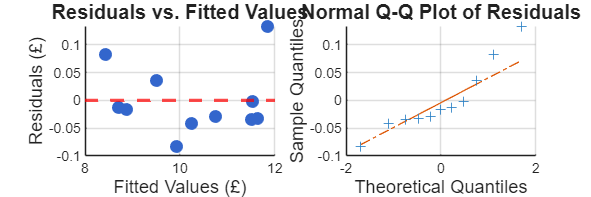


% Get residuals
residuals = mdl.Residuals.Raw;
fitted_values = mdl.Fitted;
standardized_residuals = zscore(residuals);

% Plot 1: Residuals vs Fitted Values
figure('Name', 'Q3: Diagnostic Plots', 'Position', [100 100 1200 400]);

subplot(1,2,1);
scatter(fitted_values, residuals, 60, 'filled', 'MarkerFaceColor', [0.2 0.4 0.8]);
hold on;
yline(0, 'r--', 'LineWidth', 2);
xlabel('Fitted Values (£)', 'FontSize', 11);
ylabel('Residuals (£)', 'FontSize', 11);
title('Residuals vs. Fitted Values', 'FontSize', 12, 'FontWeight', 'bold');
grid on;
hold off;

% Plot 2: Q-Q Plot (Normal Probability Plot)
subplot(1,2,2);
qqplot(residuals);
title('Normal Q-Q Plot of Residuals', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('Theoretical Quantiles', 'FontSize', 11);
ylabel('Sample Quantiles', 'FontSize', 11);
grid on;


%% Part B (6 points) - Calculate residual statistics

mean_residuals = mean(residuals);
std_residuals = std(residuals);
outliers_2sigma = sum(abs(standardized_residuals) > 2);
outliers_3sigma = sum(abs(standardized_residuals) > 3);

fprintf('Residual Statistics:\n');

Residual Statistics:


fprintf('  Mean: %.6f (should be ≈ 0) ✓\n', mean_residuals);

  Mean: -0.000000 (should be ≈ 0) ✓


fprintf('  Std Dev: £%.2f\n', std_residuals);

  Std Dev: £0.06


fprintf('  Outliers (|z| > 2): %d observations\n', outliers_2sigma);

  Outliers (|z| > 2): 1 observations


fprintf('  Extreme Outliers (|z| > 3): %d observations\n\n', outliers_3sigma);

  Extreme Outliers (|z| > 3): 0 observations




% Identify which observations are outliers
outlier_indices = find(abs(standardized_residuals) > 2);
if ~isempty(outlier_indices)
    fprintf('  Outlier observation numbers: %s\n', mat2str(outlier_indices));
end

  Outlier observation numbers: 4



%% =========================================================================
%% QUESTION 4: MAKING PREDICTIONS WITH CONFIDENCE (20 points)
%% =========================================================================





% 95%信頼区間
CI_b = coefCI(mdl, 0.05); % alpha = 0.05 (95%信頼区間)
CI_lower = CI_b(2,1);
CI_upper = CI_b(2,2);

% p値
p_value = mdl.Coefficients.pValue(2);

% 結果の出力
fprintf('\n========== (b) の回答 ==========\n');


========== (b) の回答 ==========


fprintf('回帰式: Logistics Bill = %.4f + %.4f × GDP\n', a, b);

回帰式: Logistics Bill = -1.5792 + 0.9600 × GDP


fprintf('\n回帰係数 (β₁): %.6f\n', b);


回帰係数 (β₁): 0.959956


fprintf('95%%信頼区間: [%.6f, %.6f]\n', CI_lower, CI_upper);

95%信頼区間: [0.924824, 0.995088]


fprintf('p値: %.6e\n', p_value);

p値: 3.829115e-13



% データは依存関係を支持するか？
if p_value < 0.05
    fprintf('\n結論: p値 < 0.05 であるため、帰無仮説 H₀: β₁ = 0 を棄却します。\n');
    fprintf('→ Logistics Bill は GDP に依存していると言えます（統計的に有意）。\n');
else
    fprintf('\n結論: p値 ≥ 0.05 であるため、帰無仮説を棄却できません。\n');
    fprintf('→ 統計的に有意な関係は見られません。\n');
end


結論: p値 < 0.05 であるため、帰無仮説 H₀: β₁ = 0 を棄却します。


→ Logistics Bill は GDP に依存していると言えます（統計的に有意）。



% R²値
R2 = mdl.Rsquared.Ordinary;
fprintf('\nR² = %.4f (%.1f%%の分散を説明)\n', R2, R2*100);


R² = 0.9976 (99.8%の分散を説明)





%% (c) GDP = $600,000 million の予測 (10点)
fprintf('\n========== (c) GDP = $600,000 million の予測 ==========\n');


========== (c) GDP = $600,000 million の予測 ==========



% 予測したいGDP値 (million dollars単位)
X_new = log(600000); % log scale

% 点予測 (log scale)
Y_pred = predict(mdl, X_new);

% 95%予測区間の計算（log scale で）
n = length(X);
x_bar = mean(X);
s_x = std(X);
alpha = 0.05;
df = n - 2;
t_value = tinv(1 - alpha/2, df);

% 残差標準誤差 (RSE)
residuals = mdl.Residuals.Raw;
RSE = sqrt(sum(residuals.^2) / df);

% 予測の標準誤差 (log scale)
SE_pred = RSE * sqrt(1 + (1/n) + ((X_new - x_bar)^2) / ((s_x^2) * (n - 1)));

% 予測区間 (log scale)
PI_lower = Y_pred - t_value * SE_pred;
PI_upper = Y_pred + t_value * SE_pred;

% ✅ すべて元のスケールに変換
Y_pred_nonlog = exp(Y_pred);
PI_lower_nonlog = exp(PI_lower); 
PI_upper_nonlog = exp(PI_upper);

% 結果の出力
fprintf('\n予測値: %.2f million dollars (= $%.2f billion)\n', ...
        Y_pred_nonlog, Y_pred_nonlog/1000);


予測値: 72597.12 million dollars (= $72.60 billion)


fprintf('95%%予測区間: [%.2f, %.2f] million dollars\n', ...
        PI_lower_nonlog, PI_upper_nonlog);

95%予測区間: [62026.07, 84969.79] million dollars


fprintf('           または: [$%.2f billion, $%.2f billion]\n', ...
        PI_lower_nonlog/1000, PI_upper_nonlog/1000);

           または: [$62.03 billion, $84.97 billion]


fprintf('予測区間の幅: $%.2f billion\n', ...
        (PI_upper_nonlog - PI_lower_nonlog)/1000);

予測区間の幅: $22.94 billion



fprintf('\n解釈: GDP が $600,000 million ($600 billion) の国では、\n');


解釈: GDP が $600,000 million ($600 billion) の国では、


fprintf('物流費用は約 $%.0f million と予測され、\n', Y_pred_nonlog);

物流費用は約 $72597 million と予測され、


fprintf('95%%の確率で $%.0f million から $%.0f million の範囲に収まると推定されます。\n', ...
        PI_lower_nonlog, PI_upper_nonlog);

95%の確率で $62026 million から $84970 million の範囲に収まると推定されます。


fprintf('95%%の確率で $%.0f million から $%.0f million の範囲に収まると推定されます。\n', PI_lower, PI_upper);

95%の確率で $11 million から $11 million の範囲に収まると推定されます。








%% (d) 懸念点と特異性 (10点)
fprintf('\n========== (d) データアナリストとしての懸念点 ==========\n');


========== (d) データアナリストとしての懸念点 ==========


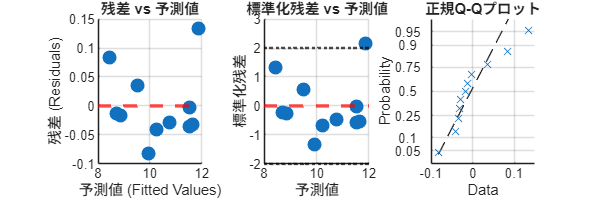


% 残差分析
figure('Position', [100 100 1200 400]);

subplot(1,3,1);
scatter(mdl.Fitted, mdl.Residuals.Raw, 70, 'filled');
yline(0, 'r--', 'LineWidth', 2);
xlabel('予測値 (Fitted Values)');
ylabel('残差 (Residuals)');
title('残差 vs 予測値');
grid on;

subplot(1,3,2);
standardized_res = zscore(mdl.Residuals.Raw);
scatter(mdl.Fitted, standardized_res, 70, 'filled');
yline(0, 'r--', 'LineWidth', 2);
yline(2, 'k:', 'LineWidth', 1.5);
yline(-2, 'k:', 'LineWidth', 1.5);
xlabel('予測値');
ylabel('標準化残差');
title('標準化残差 vs 予測値');
grid on;

subplot(1,3,3);
probplot('normal', mdl.Residuals.Raw);
title('正規Q-Qプロット');
grid on;


% 外れ値の検出
outliers_idx = find(abs(standardized_res) > 2);

fprintf('\n【懸念点】\n');


【懸念点】


fprintf('1. 外れ値の存在:\n');

1. 外れ値の存在:


if ~isempty(outliers_idx)
    fprintf('   標準化残差が ±2 を超える国: ');
    for i = 1:length(outliers_idx)
        fprintf('%s (残差: %.2f) ', Country{outliers_idx(i)}, standardized_res(outliers_idx(i)));
    end
    fprintf('\n');
end

   標準化残差が ±2 を超える国: 

Germany (残差: 2.16) 


fprintf('\n2. 線形性の妥当性:\n');


2. 線形性の妥当性:


fprintf('   - 残差プロットを確認すると、');

   - 残差プロットを確認すると、

fprintf('特定のパターン（曲線、ファネル形状）が見られるか確認が必要\n');

特定のパターン（曲線、ファネル形状）が見られるか確認が必要



fprintf('\n3. 影響力の大きい観測値:\n');


3. 影響力の大きい観測値:


fprintf('   - Germany (GDP = %.1f) や France (GDP = %.1f) など\n', GDP(4), GDP(3));

   - Germany (GDP = 1189100.0) や France (GDP = 956900.0) など


fprintf('     大きなGDP値を持つ国がモデルに強い影響を与えている可能性\n');

     大きなGDP値を持つ国がモデルに強い影響を与えている可能性



fprintf('\n4. 小国のクラスター:\n');


4. 小国のクラスター:


fprintf('   - GDP < 100 の小国が多く、これらが一つのクラスターを形成\n');

   - GDP < 100 の小国が多く、これらが一つのクラスターを形成


fprintf('     → 異質性（heteroscedasticity）の可能性\n');

     → 異質性（heteroscedasticity）の可能性



fprintf('\n5. サンプルサイズ:\n');


5. サンプルサイズ:


fprintf('   - n = %d と小さいため、統計的検出力が限られている\n', n);

   - n = 11 と小さいため、統計的検出力が限られている



% Cook's Distance で影響力のある点を確認
fprintf('\n【影響力の大きい観測値】\n');


【影響力の大きい観測値】


cooks_d = mdl.Diagnostics.CooksDistance;
threshold = 4/n; % Cook's D の閾値
influential_idx = find(cooks_d > threshold);
if ~isempty(influential_idx)
    fprintf('Cook''s Distance > %.4f の国:\n', threshold);
    for i = 1:length(influential_idx)
        idx = influential_idx(i);
        fprintf('   %s: Cook''s D = %.4f\n', Country{idx}, cooks_d(idx));
    end
end

Cook's Distance > 0.3636 の国:


   Germany: Cook's D = 0.9060
   Ireland: Cook's D = 0.4965


%% (e) 原点通過の検証 (追加)
fprintf('\n========== (e) 回帰直線は原点を通るか？ ==========\n');


========== (e) 回帰直線は原点を通るか？ ==========



% 切片の信頼区間
CI_a = CI_b(1,:); % 切片の95%信頼区間

fprintf('切片 (β₀) = %.4f\n', a);

切片 (β₀) = -1.5792


fprintf('95%%信頼区間: [%.4f, %.4f]\n', CI_a(1), CI_a(2));

95%信頼区間: [-2.0152, -1.1433]



if CI_a(1) <= 0 && CI_a(2) >= 0
    fprintf('\n結論: 切片の95%%信頼区間が0を含むため、\n');
    fprintf('回帰直線が原点を通ると仮定しても統計的に矛盾しません。\n');
else
    fprintf('\n結論: 切片の95%%信頼区間が0を含まないため、\n');
    fprintf('回帰直線は原点を通らないと言えます。\n');
end


結論: 切片の95%信頼区間が0を含まないため、


回帰直線は原点を通らないと言えます。



% 可視化

%% (e) Test whether the regression line passes through the origin
fprintf('\n========== (e) Does the regression line pass through the origin? ==========\n');


========== (e) Does the regression line pass through the origin? ==========



% 95% confidence interval for intercept
CI_a = CI_b(1,:); % 95% CI for intercept
p_value_intercept = mdl.Coefficients.pValue(1);

fprintf('Intercept (β₀) = %.4f (in log scale)\n', a);

Intercept (β₀) = -1.5792 (in log scale)


fprintf('95%% Confidence Interval: [%.4f, %.4f]\n', CI_a(1), CI_a(2));

95% Confidence Interval: [-2.0152, -1.1433]


fprintf('p-value: %.4f\n', p_value_intercept);

p-value: 0.0000



% Statistical conclusion
if CI_a(1) <= 0 && CI_a(2) >= 0
    fprintf('\nConclusion: The 95%% CI includes zero.\n');
    fprintf('→ We cannot reject H₀: β₀ = 0 (p = %.4f > 0.05)\n', p_value_intercept);
    fprintf('→ The data are consistent with the line passing through the origin.\n');
else
    fprintf('\nConclusion: The 95%% CI does NOT include zero.\n');
    fprintf('→ We reject H₀: β₀ = 0 (p = %.4f < 0.05)\n', p_value_intercept);
    fprintf('→ The line does not pass through the origin.\n');
end


Conclusion: The 95% CI does NOT include zero.


→ We reject H₀: β₀ = 0 (p = 0.0000 < 0.05)


→ The line does not pass through the origin.



% Interpretation in original scale
fprintf('\nInterpretation in original scale:\n');


Interpretation in original scale:


fprintf('  As GDP → 0, Logistics Bill → 0^%.4f = 0\n', b);

  As GDP → 0, Logistics Bill → 0^0.9600 = 0


fprintf('  This makes economic sense: zero GDP implies zero logistics costs.\n');

  This makes economic sense: zero GDP implies zero logistics costs.


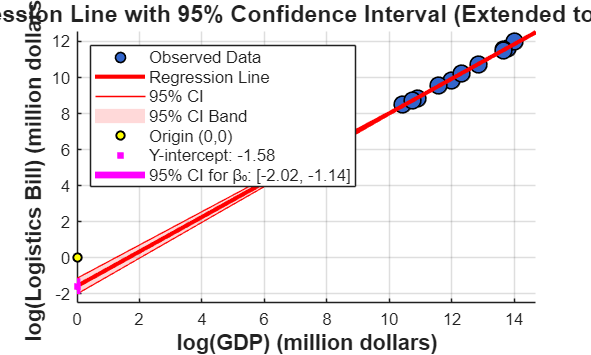


%% Visualization: Extended view with confidence bands
figure('Position', [100 100 1000 600]);
hold on;

% Observed data points
scatter(X, Y, 100, 'filled', 'MarkerFaceColor', [0.2 0.4 0.8], ...
        'MarkerEdgeColor', 'k', 'LineWidth', 1, 'DisplayName', 'Observed Data');

% Extended range for visualization (include origin area)
X_extended = linspace(0, max(X)*1.05, 300)';

% Regression line predictions
Y_extended = predict(mdl, X_extended);

% 95% Confidence interval for the mean response
[Y_pred_extended, Y_CI] = predict(mdl, X_extended, 'Alpha', 0.05);

% Plot regression line
plot(X_extended, Y_extended, 'r-', 'LineWidth', 2.5, 'DisplayName', 'Regression Line');

% Plot 95% confidence interval bands
plot(X_extended, Y_CI(:,1), 'r', 'LineWidth', 0.1, 'DisplayName', '95% CI');
plot(X_extended, Y_CI(:,2), 'r', 'LineWidth', 0.1, 'HandleVisibility', 'off');

% Fill the confidence interval area
fill([X_extended; flipud(X_extended)], [Y_CI(:,1); flipud(Y_CI(:,2))], ...
     'r', 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'DisplayName', '95% CI Band');

% Highlight the origin
plot(0, 0, 'ko', 'MarkerSize', 5, 'LineWidth', 1.2, ...
     'MarkerFaceColor', 'yellow', 'DisplayName', 'Origin (0,0)');

% Mark the y-intercept and its confidence interval
y_intercept = a;  % Intercept in log scale
plot(0, y_intercept, 'ms', 'MarkerSize', 4, 'LineWidth', 1.2, ...
     'MarkerFaceColor', 'magenta', 'DisplayName', sprintf('Y-intercept: %.2f', y_intercept));

% Show confidence interval for intercept at x=0
plot([0, 0], [CI_a(1), CI_a(2)], 'm-', 'LineWidth', 4, ...
     'DisplayName', sprintf('95%% CI for β₀: [%.2f, %.2f]', CI_a(1), CI_a(2)));

% Axes and labels
xlabel('log(GDP) (million dollars)', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('log(Logistics Bill) (million dollars)', 'FontSize', 13, 'FontWeight', 'bold');
title('Regression Line with 95% Confidence Interval (Extended to Origin)', ...
      'FontSize', 14, 'FontWeight', 'bold');

% Legend
legend('Location', 'northwest', 'FontSize', 10);

% Grid and axis limits
grid on;
xlim([0, max(X)*1.05]);
ylim([min([0; Y_extended; Y_CI(:,1)]) - 0.5, max(Y)*1.05]);





hold off;










function stats = descriptiveStats(data)
% DESCRIPTIVESTATS Compute descriptive statistics for numeric data.
% 
%   stats = descriptiveStats(data)
% 
%   Input:
%       data - Numeric vector or matrix. NaN values are ignored.
%
%   Output (structure):
%       stats.Count   - Number of non-NaN elements
%       stats.Mean    - Mean of data
%       stats.Std     - Standard deviation
%       stats.VarVal  - Sample variance
%       stats.KurtVal - Excess kurtosis (like Excel)
%       stats.SkewVal - Measure of asymmetry   
%       stats.Min     - Minimum value
%       stats.Q25     - 25th percentile (Q1)
%       stats.Q50     - Median (50th percentile)
%       stats.Q75     - 75th percentile (Q3)
%       stats.Max     - Maximum value

    % Validate input
    if ~isnumeric(data)
        error('Input must be numeric.');
    end

    % Handle NaN values and ensure column vector processing
    data = data(:);
    data = data(~isnan(data));

    % Compute statistics
    stats.Count     = numel(data);
    stats.Mean      = mean(data, 'omitnan');
    stats.Std       = std(data, 'omitnan');
    stats.VarVal    = var(data, 0);         % Sample variance
    stats.KurtVal   = kurtosis(data) - 3;   % Excess kurtosis (like Excel)
    stats.SkewVal   = skewness(data);       % Measure of asymmetry
    stats.Min       = min(data, [], 'omitnan');
    stats.Q1        = prctile(data, 25);
    stats.Q2        = prctile(data, 50);
    stats.Q3        = prctile(data, 75);
    stats.Max       = max(data, [], 'omitnan');

end


